# Machine Learning with MATLAB

Digital Twin & Automation

# Linear Regression

## Example 1: Fit with Linear Regression 

**Data Acquisition**

- Feature: One-Dimension,  p=1

- True value: ytrue = 2X+3

clear

x = randn(100,1);
y = x*2 + 3+randn(100,1);

**Fit Linear Regression**

mdl = fitlm(x,y)

mdl = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)     3.0217      0.10164    29.729    7.7214e-51
    x1              1.9352     0.095263    20.314    6.6442e-37


Number of observations: 100, Error degrees of freedom: 98
Root Mean Squared Error: 1.01
R-squared: 0.808,  Adjusted R-Squared: 0.806
F-statistic vs. constant model: 413, p-value = 6.64e-37

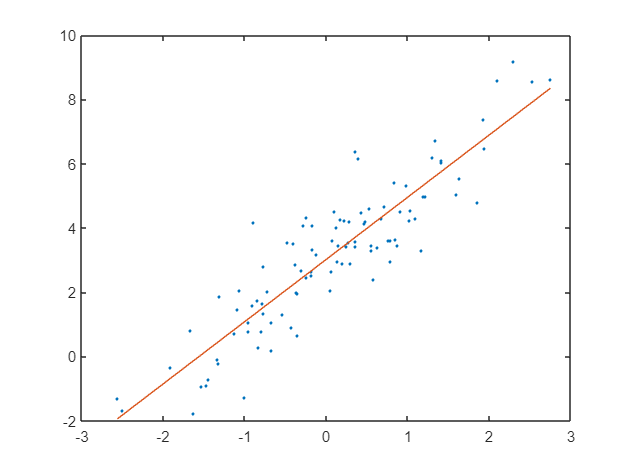


% Plot prediction
plot(x,y,'.',x,mdl.Fitted, '-')

**Anlayze Linear Regression**

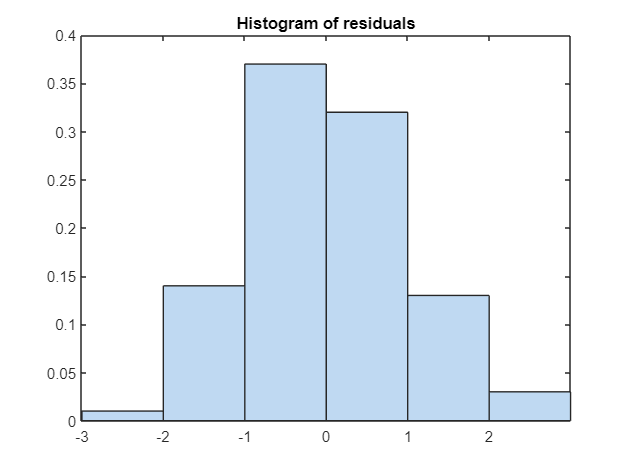

% Plot residual histogram
plotResiduals(mdl)


% From remove outlier from histogram
outl = find(abs(mdl.Residuals.Raw) > 2);
mdl.Residuals.Raw(outl)

ans =     2.3690
    2.8692
    2.6843
   -2.3620



% Fit with outlier removed
mdl2 = fitlm(x,y,'Exclude',outl)

mdl2 = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)     2.9648     0.090727    32.678    4.0493e-53
    x1               1.925     0.084096     22.89    3.2418e-40


Number of observations: 96, Error degrees of freedom: 94
Root Mean Squared Error: 0.885
R-squared: 0.848,  Adjusted R-Squared: 0.846
F-statistic vs. constant model: 524, p-value = 3.24e-40

**Predict with Test data**

% Ypredict and confidence interval
Xnew=2;
% y=7 %true
[Ynew,YnewI] = predict(mdl2,Xnew)

Ynew = 6.8147

YnewI =     6.4503    7.1792


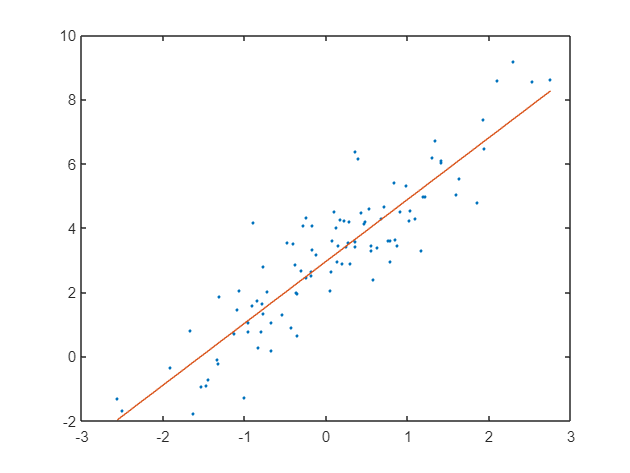


% Plot prediction
plot(x,y,'.',x,mdl2.Fitted, '-')

## Example 2: Predict Car MPG

Find linear relationship of  MPG(연비) with   Weight & Displacement

Then, Predict MPG for a car with Weight=3000 , Displacement=300

**Data Acquisition**

-  Dependet Variable:  MPG

- Independet Variables: Weight, Displacement

clear
load carsmall

tbl = table(MPG,Weight, Displacement);  % table type

**Fit  Linear Regression**

mdl = fitlm(tbl,'MPG~Weight+Displacement')

mdl = Linear regression model:
    MPG ~ 1 + Weight + Displacement

Estimated Coefficients:
                     Estimate        SE         tStat       pValue  
                    __________    _________    _______    __________

    (Intercept)         46.925       2.0858     22.497    6.0509e-39
    Weight          -0.0068422    0.0011337    -6.0353    3.3838e-08
    Displacement     -0.014593    0.0082695    -1.7647      0.080968


Number of observations: 94, Error degrees of freedom: 91
Root Mean Squared Error: 4.09
R-squared: 0.747,  Adjusted R-Squared: 0.741
F-statistic vs. constant model: 134, p-value = 7.22e-28

mdl.CoefficientNames

ans = 1×3 cell array
    {'(Intercept)'}    {'Weight'}    {'Displacement'}


mdl.Coefficients.Estimate

ans =    46.9247
   -0.0068
   -0.0146


**Analyze, Modify**

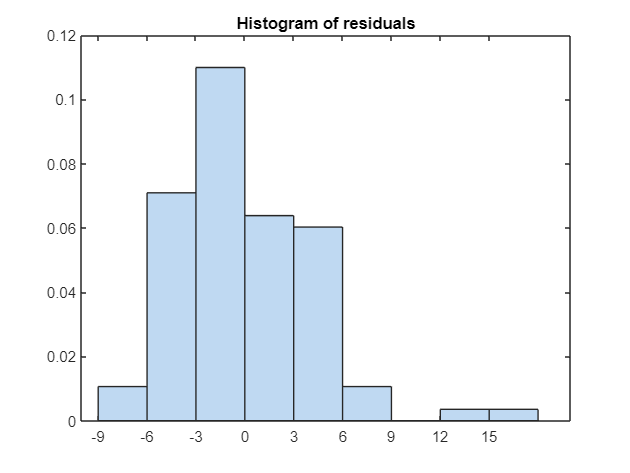

plotResiduals(mdl)


% Remove outlier
outl = find((mdl.Residuals.Raw) > 9);

% Fit with outlier removed
mdl2 = fitlm(tbl,'MPG~Weight+Displacement','Exclude',outl)

mdl2 = Linear regression model:
    MPG ~ 1 + Weight + Displacement

Estimated Coefficients:
                     Estimate         SE         tStat       pValue  
                    __________    __________    _______    __________

    (Intercept)         45.548        1.8056     25.226    2.5559e-42
    Weight          -0.0062503    0.00097845    -6.3879    7.4767e-09
    Displacement     -0.018035     0.0071414    -2.5255      0.013324


Number of observations: 92, Error degrees of freedom: 89
Root Mean Squared Error: 3.51
R-squared: 0.796,  Adjusted R-Squared: 0.792
F-statistic vs. constant model: 174, p-value = 1.78e-31

mdl2.Coefficients.Estimate

ans =    45.5477
   -0.0063
   -0.0180


**Predict**

Detailed look at the interactions 

% Ypredict and confidence interval
Xnew=[3000 300]; 
[Ynew,YnewI]=predict(mdl2,Xnew)

Ynew = 21.3863

YnewI =    19.8515   22.9211


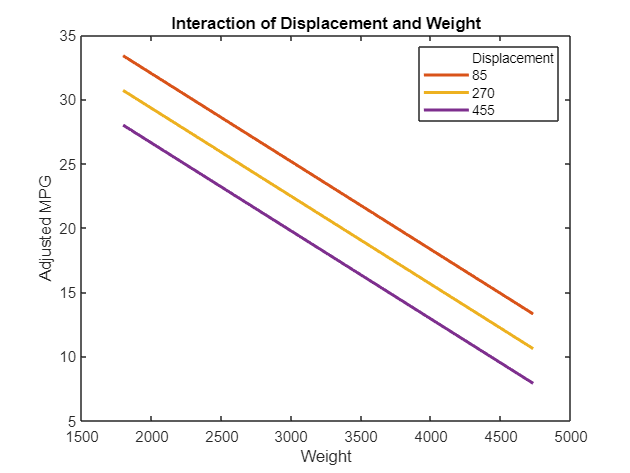


plotInteraction(mdl,'Displacement','Weight','predictions')

# Exercise

## Exercise 1 :  Using Gradient Descent

**Linear Regression Using Gradient Descent**

Hypothesis. 

To find the parameters, repeat until convergence

where

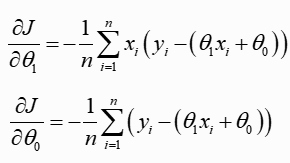

**Data Acquisition**

Feature: One-Dimension,  p=1

True: y = 2X+3

clear

N=100;
X = randn(N,1);
Y = X*2 + 3+randn(N,1);

%  Variable
lamda=0.1

lamda = 0.1000

k = 0

t0 = 0.5;
t1 = 0.5;
e = 1;
itrN = 1000;
k=0

**Fit Linear Regression:  Gradient Descent**

while(e > 0.001 || k < itrN)
    
    h = t1 .* X + t0;

    dJt1 = (-1) * mean(X .* (Y-h));
    dJt0 = (-1) * mean(Y - h);

    t1_new = t1 - lamda .* dJt1;
    t0_new = t0 - lamda .* dJt0;

    e = 0.5 * (abs((t1_new-t1))+abs((t0_new-t0)));
    
    t1 = t1_new;
    t0 = t0_new;

    k=k+1;

end
% Predicted hypothesis y(x)
ypred = t1 * X + t0; 


disp('optimal paraterms are')

optimal paraterms are


t1

t1 = 2.0328

t0

t0 = 3.1028

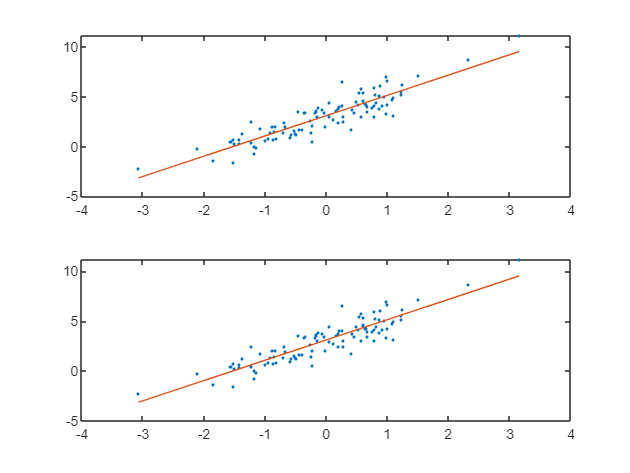

% MATLAB fit linear 
mdl = fitlm(X,Y);

% Plot and compare predictions
figure
subplot(2,1,1)
plot(X,Y,'.',X,mdl.Fitted, '-')
subplot(2,1,2)
plot(X,Y,'.',X,ypred, '-')

## Exercise 2 :  Linear Regression with p=2

Find the linear regression. Remove Outlier and predict a test value Xtest=[2;1];.  You can use MATLAB fitlm()

- Feature: 2-Dimensions,  p=2

- True value: y = 2*X1+4*X2+3

**Data Acquisition**

clear

X = randn(100,2);
Y = X * [2;4] + 3+ randn(100,1);

%  Variable
lamda=0.1
t0 = 0.5;
t1 = 0.5;
t2 = 0.5;

e = 1;
itrN = 1000;
k=0

while(e > 0.001 || k < itrN)
    
    h = X * [t1 ; t2] + t0;
    
    dJt2 = -(mean(X(:, 2) .* (Y - h)));
    dJt1 = -(mean(X(:, 1) .* (Y - h)));
    dJt0 = (-1) * mean(Y - h);
    
    t2_new = t2 - lamda .* dJt2;
    t1_new = t1 - lamda .* dJt1;
    t0_new = t0 - lamda .* dJt0;

    e = 0.5 * (abs((t2_new - t2)) + abs((t1_new - t1)) + abs((t0_new - t0)));
    
    t2 = t2_new;
    t1 = t1_new;
    t0 = t0_new;

    k=k+1;

end
% Predicted hypothesis y(x)
ypred =  X * [t1 ; t2] + t0;

disp('optimal paraterms are')
t2
t1
t0

## Exercise 3:  Linear Regression with p=4

Find linear relationship of 

- MPG ~ 1 + Acceleration + Displacement + Horsepower + Weight 

Choose a test data and predict

**Data Acquisition**

% load carsmall
clear;

load carsmall

% table type
tbl = table(MPG,Weight, Displacement);  

mdl = fitlm(tbl,'MPG~Weight+Displacement')

**Fit  Linear Regression**

**Analyze, Modify**

% Remove outlier



**Predict**

Predict for a Test value